## ECE 537 : Assignment 3

Group 9 - Ashlynn Steeves, Derrell D'Souza

close all;
clear all;
clc;

**Task 1** - Use Matlab’s neural network tool box to create a 3 class decision classifier for the 3 class data generated in Exercise 1.

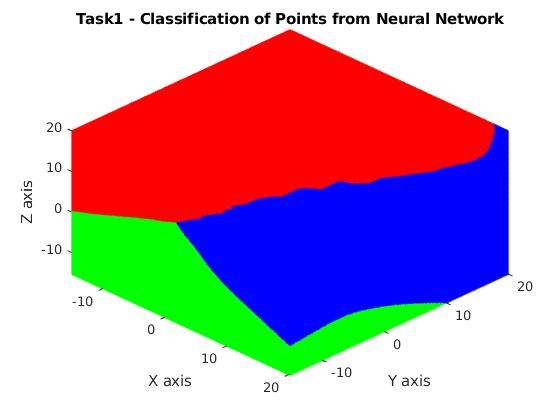

K = 1000;
D = 3;

% Dataset A
mu_A = [0 4 7];
sigma_A = [6.5000 2.1651 1.2500 ; 2.1651 5.1250 2.3816;1.2500 2.3816 2.3750];
data_A = gaussian_data_from_ss(K,D,mu_A,sigma_A);

% Dataset B
mu_B = [10 5 5];
sigma_B = [3.0184 0.4331 -1.4481; 0.4331 0.9436 -0.6456 ;-1.4481 -0.6456 1.2880];
data_B = gaussian_data_from_ss(K,D,mu_B,sigma_B);

% Dataset C
mu_C = [-2 -5 -5];
sigma_C = [6.8928 -1.3750 3.1945 ;-1.3750 3.3572 0.6945;3.1945 0.6945 3.7500];
data_C = gaussian_data_from_ss(K,D,mu_C,sigma_C);

input_data = [data_A; data_B; data_C];

target = [1*ones(K,1); 2*ones(K,1); 3*ones(K,1)];
target_new = bsxfun(@eq, target(:), 1:max(target));

Npt = 200; 
Vaxis = [-15 20 -15 20 -15 20];
volume = vol3D(Vaxis,Npt);

NN_Classification_T1  = nprtool_fun(input_data, target_new, volume, 10, 70, 15, 15);
figure(1)
vis_pts_T1 = visualize_points(NN_Classification_T1,volume);
title('Task1 - Classification of Points from Neural Network')

**Task 2** - Plot the decision boundaries created by this trained neural network classifier and discuss the ”correctness” of these boundaries versus the Bayesian class boundaries that were generated in Exercise 1. 

Solution: 

The bayes decision boundary provides the optimal solution to the general decision problem due to the known probability structure underlying the categories.

Although the Bayesian rule provides the optimal solution with respect to the classification error probability, its application requires the estimation of the respective conditional PDFs; this is not an easy task once the dimensionality of the feature space assumes relatively large values. This paves the way for considering neural networks.

One may wonder how a performance close to the optimal classifier can be obtained, even in theory and asymptotically, because the Bayesian classifier exploits the statistical information for the data distribution while the neural network does not take into account such information

Neural network try to optimize it so as to minimize the respective empirical loss. The form of non-linearit is learned from the training data.

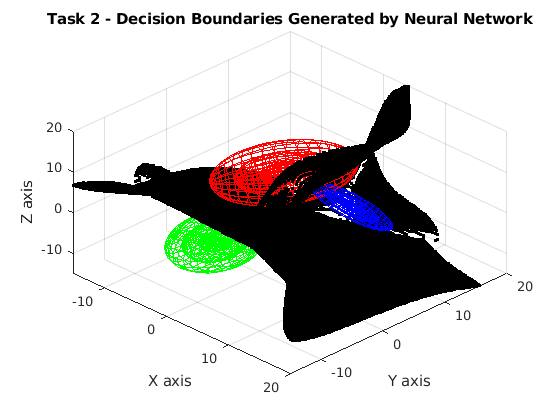

figure(2);
change_val = zeros(200^3,1);
for i = 1:40000
    change_val((i-1)*200+1 :200*i,:)  = [0; diff(NN_Classification_T1((i-1)*200+1 :200*i))];
end 
b = volume(change_val~= 0,:);
axes_plot = visualize_boundary(data_A, data_B, data_C, b);
title('Task 2 - Decision Boundaries Generated by Neural Network')

**Task 3 **- Discuss whether or not (and why) Matlab’s computation of the trained neural network’s error, as implemented within its neural net toolbox, is correct.

- Type command to see whats under the hood 

**Task 4** - Perform 10 different neural network trainings, each using different random seeds, and discuss the variability that arises in the produced interclass decision boundaries.

Solution:

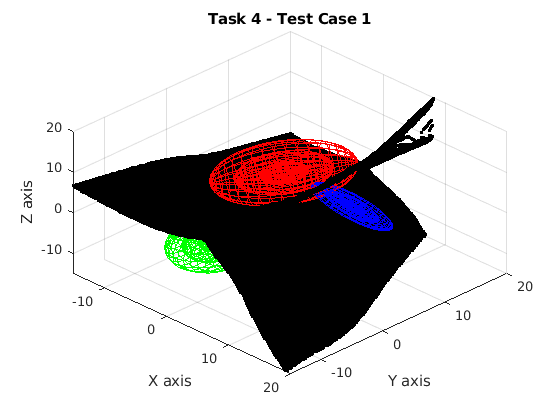

layers = 10;
training_per = 70; 
testing_per = 15;
validation_per = 15; 

% Test Case 1 
NN_Classification_T4_1  = nprtool_fun(input_data, target_new, volume, layers, training_per, testing_per, validation_per);
change_val_T4_1 = zeros(200^3,1); 
for i = 1:40000
    change_val_T4_1((i-1)*200+1 :200*i,:)  = [0; diff(NN_Classification_T4_1((i-1)*200+1 :200*i))]; % Finds points where classification of points in volume changes
end 
b_T4_1 = volume(change_val_T4_1~= 0,:); % Subset of volume where points change (describes the decision boundary)
figure(3)
vis_boundary_T4_1 = visualize_boundary(data_A, data_B, data_C, b_T4_1);
title('Task 4 - Test Case 1')

% Test Case 2 
NN_Classification_T4_2  = nprtool_fun(input_data, target_new, volume, layers, training_per, testing_per, validation_per);

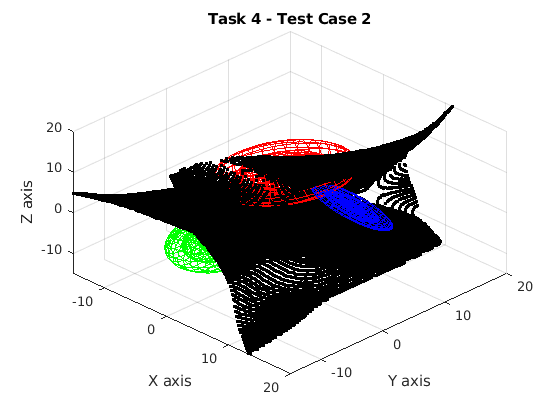

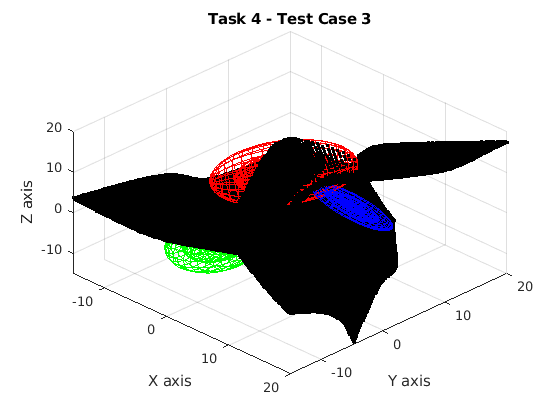

change_val_T4_2 = zeros(200^3,1); 
for i = 1:40000
    change_val_T4_2((i-1)*200+1 :200*i,:)  = [0; diff(NN_Classification_T4_2((i-1)*200+1 :200*i))]; % Finds points where classification of points in volume changes
end 
b_T4_2 = volume(change_val_T4_2~= 0,:); % Subset of volume where points change (describes the decision boundary)
figure(4)
vis_boundary_T4_2 = visualize_boundary(data_A, data_B, data_C, b_T4_2);
title('Task 4 - Test Case 2')

% Test Case 3 
NN_Classification_T4_3  = nprtool_fun(input_data, target_new, volume, layers, training_per, testing_per, validation_per);
change_val_T4_3  = zeros(200^3,1); 
for i = 1:40000
    change_val_T4_3((i-1)*200+1 :200*i,:)  = [0; diff(NN_Classification_T4_3((i-1)*200+1 :200*i))]; % Finds points where classification of points in volume changes
end 
b_T4_3 = volume(change_val_T4_3~= 0,:); % Subset of volume where points change (describes the decision boundary)
figure(5)
vis_boundary_T4_3 = visualize_boundary(data_A, data_B, data_C, b_T4_3);
title('Task 4 - Test Case 3')

% Test Case 4 
NN_Classification_T4_4  = nprtool_fun(input_data, target_new, volume, layers, training_per, testing_per, validation_per);

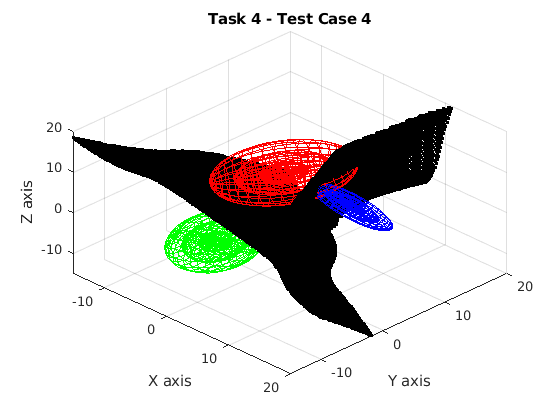

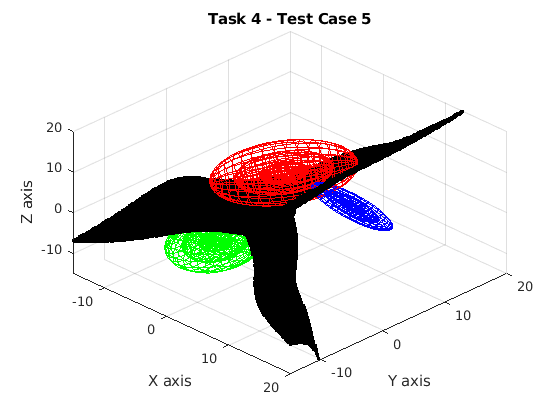

change_val_T4_4  = zeros(200^3,1); 
for i = 1:40000
    change_val_T4_4((i-1)*200+1 :200*i,:)  = [0; diff(NN_Classification_T4_4((i-1)*200+1 :200*i))]; % Finds points where classification of points in volume changes
end 
b_T4_4 = volume(change_val_T4_4~= 0,:); % Subset of volume where points change (describes the decision boundary)
figure(6)
vis_boundary_T4_4 = visualize_boundary(data_A, data_B, data_C, b_T4_4);
title('Task 4 - Test Case 4')

% Test Case 5 
NN_Classification_T4_5  = nprtool_fun(input_data, target_new, volume, layers, training_per, testing_per, validation_per);
change_val_T4_5 = zeros(200^3,1); 
for i = 1:40000
    change_val_T4_5((i-1)*200+1 :200*i,:)  = [0; diff(NN_Classification_T4_5((i-1)*200+1 :200*i))]; % Finds points where classification of points in volume changes
end 
b_T4_5 = volume(change_val_T4_5~= 0,:); % Subset of volume where points change (describes the decision boundary)
figure(7)
vis_boundary_T4_5 = visualize_boundary(data_A, data_B, data_C, b_T4_5);
title('Task 4 - Test Case 5')

% Test Case 6 
NN_Classification_T4_6  = nprtool_fun(input_data, target_new, volume, layers, training_per, testing_per, validation_per);

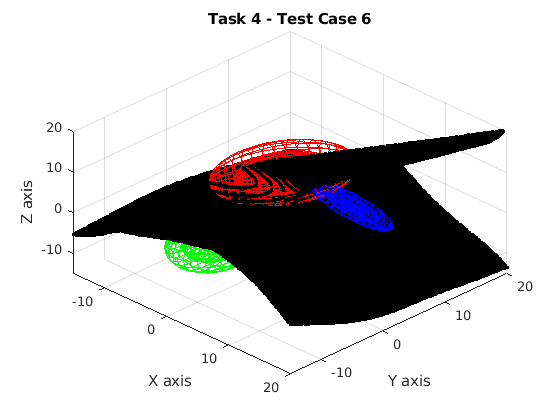

change_val_T4_6 = zeros(200^3,1); 
for i = 1:40000
    change_val_T4_6((i-1)*200+1 :200*i,:)  = [0; diff(NN_Classification_T4_6((i-1)*200+1 :200*i))]; % Finds points where classification of points in volume changes
end 
b_T4_6 = volume(change_val_T4_6~= 0,:); % Subset of volume where points change (describes the decision boundary)
figure(8)
vis_boundary_T4_6 = visualize_boundary(data_A, data_B, data_C, b_T4_6);
title('Task 4 - Test Case 6')

% Test Case 7 
NN_Classification_T4_7  = nprtool_fun(input_data, target_new, volume, layers, training_per, testing_per, validation_per);
change_val_T4_7 = zeros(200^3,1); 
for i = 1:40000
    change_val_T4_7((i-1)*200+1 :200*i,:)  = [0; diff(NN_Classification_T4_7((i-1)*200+1 :200*i))]; % Finds points where classification of points in volume changes
end 
b_T4_7 = volume(change_val_T4_7~= 0,:); % Subset of volume where points change (describes the decision boundary)
figure(9)
vis_boundary_T4_7 = visualize_boundary(data_A, data_B, data_C, b_T4_7);
title('Task 4 - Test Case 7')

% Test Case 8 
NN_Classification_T4_8  = nprtool_fun(input_data, target_new, volume, layers, training_per, testing_per, validation_per);

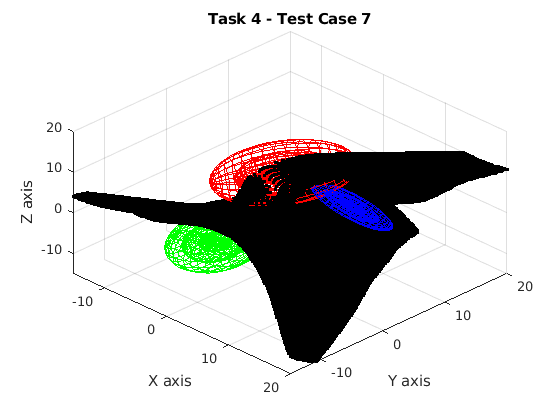

change_val_T4_8 = zeros(200^3,1); 
for i = 1:40000
    change_val_T4_8((i-1)*200+1 :200*i,:)  = [0; diff(NN_Classification_T4_8((i-1)*200+1 :200*i))]; % Finds points where classification of points in volume changes
end 
b_T4_8 = volume(change_val_T4_8~= 0,:); % Subset of volume where points change (describes the decision boundary)
figure(10)
vis_boundary_T4_8 = visualize_boundary(data_A, data_B, data_C, b_T4_8);
title('Task 4 - Test Case 8')

% Test Case 9 
NN_Classification_T4_9  = nprtool_fun(input_data, target_new, volume, layers, training_per, testing_per, validation_per);

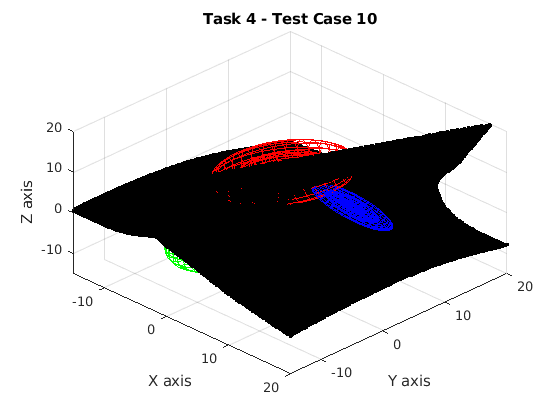

change_val_T4_9 = zeros(200^3,1); 
for i = 1:40000
    change_val_T4_9((i-1)*200+1 :200*i,:)  = [0; diff(NN_Classification_T4_9((i-1)*200+1 :200*i))]; % Finds points where classification of points in volume changes
end 
b_T4_9 = volume(change_val_T4_9~= 0,:); % Subset of volume where points change (describes the decision boundary)
figure(11)
vis_boundary_T4_9 = visualize_boundary(data_A, data_B, data_C, b_T4_9);
title('Task 4 - Test Case 9')

% Test Case 10 
NN_Classification_T4_10  = nprtool_fun(input_data, target_new, volume, layers, training_per, testing_per, validation_per);
change_val_T4_10 = zeros(200^3,1); 
for i = 1:40000
    change_val_T4_10((i-1)*200+1 :200*i,:)  = [0; diff(NN_Classification_T4_10((i-1)*200+1 :200*i))]; % Finds points where classification of points in volume changes
end 
b_T4_10 = volume(change_val_T4_10~= 0,:); % Subset of volume where points change (describes the decision boundary)
figure(12)
vis_boundary_T4_10 = visualize_boundary(data_A, data_B, data_C, b_T4_10);
title('Task 4 - Test Case 10')

** Discuss what would occur relative to the produced decision boundaries if 100 different neural network training were conducted.**

Training the neural network multiple times will generate different results each time due to different randomized initial conditions and sampling. Therefore, 100 different neural network training's will not have any positive impact on the produced decision boundary.

** Discuss which of the resulting neural network decision boundaries is the correct (or more correct) boundary.**

The difference between the decision boundaries generated in the test cases above is the random seed used to initialize the classifier. Therefore, the case of which decision boundary is more correct is ultimatley dependant on chance. However, under these circumstances, we can state that whichever resulting descion boundary is most similar to the bayes decision boundary generated for the same three classes would be the most "correct". 

 **Discuss how the nature of the neural network decision boundaries would change as increasingly more neurons are added to the neural network’s hidden layer(s). **

The number of neurons, or hidden units, between layers governs the expressive power of the net and consequentially the complexity of the descision boundary. For classes that are well seperated or linearly seperable few hidden units are required, and as the complexity of the classes and their interconnection increases so does the need for hidden units. Therefore, as we incerase the number of hidden units we would expect to see an imporvement in the decision bounaries generated by the neural network. It is worth noting, that for practical application, passed a certain threshold (which depends on the complexity of the data at hand) the addition of more hidden units will case the decision boundaries to overfit to the training data resulting in low generlizability and high rates of testing error.

**Task 5** - Discuss in detail why or why not the neural network will ever be able to produce decision boundaries equivalent to the Bayes boundaries. 

**Task 6** - Assess whether or not the neural network boundaries are more or less sensitive to outliers than the Bayesian boundaries.

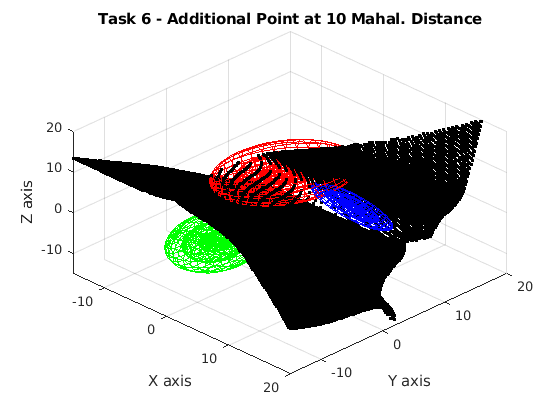

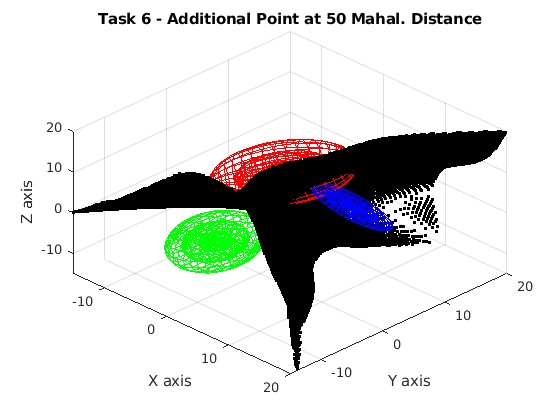

target_T6 = [1*ones(K,1); 2*ones(K+1,1); 3*ones(K,1)];
target_new_T6 = bsxfun(@eq, target_T6(:), 1:max(target_T6));

% New point at 10 mahalanobis distance
pt_mal_10 = additional_pts(mu_B, sigma_B, 10)'; % Finding a point at the desired mahalanobis distance 
class_B_p10 = [data_B;pt_mal_10]; % Adding the new point to the original dataset A 
input_data_p10 = [data_A; class_B_p10; data_C];

NN_Classification_T6_10  = nprtool_fun(input_data_p10, target_new_T6, volume, 10,70, 15, 15);
change_val_T6_10 = zeros(200^3,1); 
for i = 1:40000
    change_val_T6_10((i-1)*200+1 :200*i,:)  = [0; diff(NN_Classification_T6_10((i-1)*200+1 :200*i))]; % Finds points where classification of points in volume changes
end 
b_T6_10 = volume(change_val_T6_10~= 0,:); % Subset of volume where points change (describes the decision boundary)
figure(13)
vis_boundary_T6_10 = visualize_boundary(data_A, class_B_p10, data_C, b_T6_10);
title('Task 6 - Additional Point at 10 Mahal. Distance')

% New point at 50 mahalanobis distance
pt_mal_50 = additional_pts(mu_B, sigma_B, 50)'; % Finding a point at the desired mahalanobis distance 
class_B_p50 = [data_B;pt_mal_50]; % Adding the new point to the original dataset A 
input_data_p50 = [data_A; class_B_p50; data_C];

NN_Classification_T6_50  = nprtool_fun(input_data_p50, target_new_T6, volume, 10,70, 15, 15);
change_val_T6_50 = zeros(200^3,1); 
for i = 1:40000
    change_val_T6_50((i-1)*200+1 :200*i,:)  = [0; diff(NN_Classification_T6_50((i-1)*200+1 :200*i))]; % Finds points where classification of points in volume changes
end 
b_T6_50 = volume(change_val_T6_50~= 0,:); % Subset of volume where points change (describes the decision boundary)
figure(14)
vis_boundary_T6_50 = visualize_boundary(data_A, class_B_p50, data_C, b_T6_50);
title('Task 6 - Additional Point at 50 Mahal. Distance')

% New point at 100 mahalanobis distance 
pt_mal_100 = additional_pts(mu_B, sigma_B, 100)'; % Finding a point at the desired mahalanobis distance 
class_B_p100 = [data_B;pt_mal_100]; % Adding the new point to the original dataset A 
input_data_p100 = [data_A; class_B_p100; data_C];

NN_Classification_T6_100  = nprtool_fun(input_data_p100, target_new_T6, volume, 10,70, 15, 15);

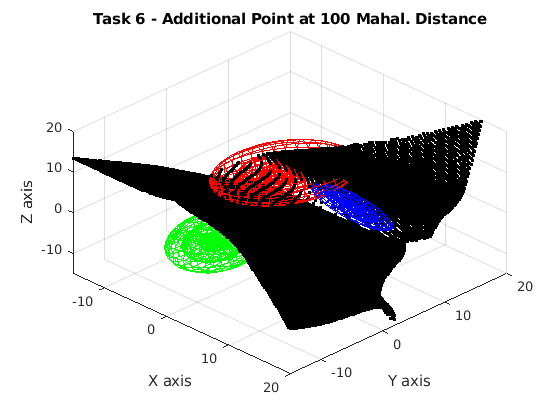

change_val_T6_100 = zeros(200^3,1); 
for i = 1:40000
    change_val_T6_100((i-1)*200+1 :200*i,:)  = [0; diff(NN_Classification_T6_100((i-1)*200+1 :200*i))]; % Finds points where classification of points in volume changes
end 
b_T6_100 = volume(change_val_T6_100~= 0,:); % Subset of volume where points change (describes the decision boundary)
figure(15)
vis_boundary_T6_100 = visualize_boundary(data_A, class_B_p10, data_C, b_T6_10);
title('Task 6 - Additional Point at 100 Mahal. Distance')

**Comments: **

Because the boundaries generated by the neural networks are dependant on random initial conditions we expect variation each time they are generated (as demonstrated in task 4). This makes it difficult to visualy analyze the direct impact of outliers on neural network boundaries. However, it does seem that the variation in boundaries resulting from the addition of a single point is far less dramatic than it was in assignment 2 when the same test was applied to bayes decision boundaries. This makes sense since the boundaries here generated by a neural network are based on labeled data rather than summary statistics of the given classes (as they are for bayesian classification) which can be heavily impacted by a single point. 

**Task 7** - Discuss the trade-offs that occur between generalizability and overfitting as the ratio of training data to test data is changed, i.e., for example from 90:10 to 10:90.

function f = gaussian_data_from_ss(K,D,mu,sigma)
    N = randn(K,D); % Generate a subset of K D-dimensional samples from a normal distribution
    N_c = N - mean(N); % Centralize the data at zero-mean
    
    [v,d] = eig(cov(N_c)); % Obtain eigen values and eigen vectors for covariance of N    
    R = v*inv(sqrt(d)); % Generate the whitening transform
    W  = N_c*R; % Apply the whitening transform on the centralized data
    
    [vn,dn] = eig(sigma); % Obtain eigen values and eigen vectors of the desired covariance
    R_inv = sqrt(dn)*inv(vn); % Generate the inverse whitening transform
    f = W*R_inv; % Apply the inverse whitening transfrom on the whitened gaussian data 
    f = f + mu; % Centralize the data at the desired mu
end 

function[new_pt] = additional_pts(mu, sigma, desired_mah)
    [V, D] = eig(sigma);

    principal_axes = sqrt(desired_mah)*((V)*sqrt(D))+mu'; % Principal axes extended to the appropriate length to acheive desired mahalanobis disance
    new_pt = principal_axes(:,1); % Choosing the new point along the 1st principal axes ( this choice is arbatrary)    

end


function NN_classification = nprtool_fun(input_data, target_data, testing_data, layers, training_per, testing_per, validation_per)
% NPRTOOL generated script 
x = input_data';
t = target_data';

% Choose a Training Function
% For a list of all training functions type: help nntrain
% 'trainlm' is usually fastest.
% 'trainbr' takes longer but may be better for challenging problems.
% 'trainscg' uses less memory. Suitable in low memory situations.
trainFcn = 'trainscg';  % Scaled conjugate gradient backpropagation.

% Create a Pattern Recognition Network
hiddenLayerSize = layers;
net = patternnet(hiddenLayerSize, trainFcn);

% Setup Division of Data for Training, Validation, Testing
net.divideParam.trainRatio = training_per/100;
net.divideParam.valRatio = validation_per/100;
net.divideParam.testRatio = testing_per/100;

% Train the Network
[net,tr] = train(net,x,t);

% % Test the Network
% y = net(x);
% e = gsubtract(t,y);
% performance = perform(net,t,y)
% tind = vec2ind(t);
% yind = vec2ind(y);
% percentErrors = sum(tind ~= yind)/numel(tind);
% 
% % View the Network
% view(net)
% 
% % Plots
% % Uncomment these lines to enable various plots.
% %figure, plotperform(tr)
% %figure, plottrainstate(tr)
% %figure, ploterrhist(e)
% %figure, plotconfusion(t,y)
% %figure, plotroc(t,y)

%Changes made to generated script to test generated model on volume data
% Test the Network on volume data
y = net(testing_data');
yind = vec2ind(y);
NN_classification = yind';
end

function axes_plot = visualize_points(class_index,V)

    XA = V(class_index == 1,:);
    XB = V(class_index == 2,:);
    XC = V(class_index == 3,:);
    
    axes_plot = axes;
    hold(axes_plot,'on');
    plot3(XA(:,1),XA(:,2),XA(:,3),'Marker','.','LineStyle','none','Color','r');
    plot3(XB(:,1),XB(:,2),XB(:,3),'Marker','.','LineStyle','none','Color','b');
    plot3(XC(:,1),XC(:,2),XC(:,3),'Marker','.','LineStyle','none','Color','g');
    
    xlabel('X axis');
    ylabel('Y axis');
    zlabel('Z axis');
    
    xlim(axes_plot,[-15 20]);
    ylim(axes_plot,[-15 20]);
    zlim(axes_plot,[-15 20]);
    view(axes_plot,[45 45]);
    grid(axes_plot,'on');
    hold(axes_plot,'off');
end


function [x1,y1,z1,x2,y2,z2,x3,y3,z3] = ellipse_cord(data)

    mu = mean(data);
    sigma = cov(data);
    [v,d] = eig(sigma);
    %plot ellipsoid for three standard deviations
    radius = sqrt(diag(d));
    [x1,y1,z1] = ellipsoid(0, 0, 0, radius(1),radius(2),radius(3));
    [x2,y2,z2] = ellipsoid(0, 0, 0, 2*radius(1),2*radius(2),2*radius(3));
    [x3,y3,z3] = ellipsoid(0, 0, 0, 3*radius(1),3*radius(2),3*radius(3));
    

    x1 = kron(v(:,1),x1);y1 = kron(v(:,2),y1);z1 = kron(v(:,3),z1);
    x2 = kron(v(:,1),x2);y2 = kron(v(:,2),y2);z2 = kron(v(:,3),z2);
    x3 = kron(v(:,1),x3);y3 = kron(v(:,2),y3);z3 = kron(v(:,3),z3);
    dat1 = x1 + y1 + z1; dat2 = x2 + y2 + z2 ; dat3 = x3 + y3 + z3; % to account for rotation of all three axis 
    n = size(dat1,2);
    x1 = dat1(1:n,:) + mu(1); y1 = dat1(n+1:2*n,:) + mu(2); z1 = dat1(2*n+1:end,:) + mu(3); 
    x2 = dat2(1:n,:) + mu(1); y2 = dat2(n+1:2*n,:) + mu(2); z2 = dat2(2*n+1:end,:) + mu(3);
    x3 = dat3(1:n,:) + mu(1); y3 = dat3(n+1:2*n,:) + mu(2); z3 = dat3(2*n+1:end,:) + mu(3); 
end 

function val = gaussian_density(mu,sigma,X)
%finds the gaussian pdf 
    [k,d] = size(X);
    X0 = bsxfun(@minus,X,mu);
    [R,err] = cholcov(sigma,0);
    xRinv = X0 / R;
    % determinant of sigma is product of diagonal elements of cholesky decomposition
    logSqrtDetSigma = sum(log(diag(R))); 
    quadratic = sum(xRinv.^2, 2);
    val = exp(-0.5*quadratic - logSqrtDetSigma - d*log(2*pi)/2);
end 

function axes_plot = visualize_boundary(data_A, data_B, data_C, b)

    mu_A = mean(data_A);
    mu_B = mean(data_B);
    mu_C = mean(data_C);

    sigma_A = cov(data_A);
    sigma_B = cov(data_B);
    sigma_C = cov(data_C);

    [vA,dA] = eig(sigma_A);
    [vB,dB] = eig(sigma_B);
    [vC,dC] = eig(sigma_C);

    axes_plot = axes;
    hold(axes_plot,'on');
    [xA1,yA1,zA1,xA2,yA2,zA2,xA3,yA3,zA3] = ellipse_cord(data_A);
    surf(xA1, yA1, zA1,'EdgeColor', 'r','FaceAlpha',0);
    surf(xA2, yA2, zA2, 'EdgeColor', 'r','FaceAlpha',0);
    surf(xA3, yA3, zA3,'EdgeColor', 'r','FaceAlpha',0);
    [xB1,yB1,zB1,xB2,yB2,zB2,xB3,yB3,zB3] = ellipse_cord(data_B);
    surf(xB1, yB1, zB1,'EdgeColor', 'b','FaceAlpha',0);
    surf(xB2, yB2, zB2, 'EdgeColor', 'b','FaceAlpha',0);
    surf(xB3, yB3, zB3,'EdgeColor', 'b','FaceAlpha',0);
    [xC1,yC1,zC1,xC2,yC2,zC2,xC3,yC3,zC3] = ellipse_cord(data_C);
    surf(xC1, yC1, zC1,'EdgeColor', 'g','FaceAlpha',0);
    surf(xC2, yC2, zC2, 'EdgeColor', 'g','FaceAlpha',0);
    surf(xC3, yC3, zC3,'EdgeColor', 'g','FaceAlpha',0);

    %plot decision boundaries
    plot3(b(:,1),b(:,2),b(:,3),'Marker','.','LineStyle','none','Color','k');
    % Create zlabel
    zlabel('Z axis');

    % Create ylabel
    ylabel('Y axis');

    % Create xlabel
    xlabel('X axis');

    % Create title

    xlim(axes_plot,[-15 20]);
    ylim(axes_plot,[-15 20]);
    zlim(axes_plot,[-15 20]);
    view(axes_plot,[45 45]);
    grid(axes_plot,'on');
    hold(axes_plot,'off');
end


function V = vol3D(Vaxis,Num) 
    NV = Num;
    
    if length(Vaxis) == 2
        Vaxis = [Vaxis Vaxis Vaxis];
    end
    
    min_a = Vaxis(1);
    max_a = Vaxis(2);
    res = (max_a-min_a)/(NV-1);
    
    r = min_a:res:max_a;
    r = r(:);
    
    rx = [Vaxis(1):(Vaxis(2)-Vaxis(1))/(NV-1):Vaxis(2)]';
    ry = [Vaxis(3):(Vaxis(4)-Vaxis(3))/(NV-1):Vaxis(4)]';
    rz = [Vaxis(5):(Vaxis(6)-Vaxis(5))/(NV-1):Vaxis(6)]';
    
    x = zeros(3,length(rz)^3);
    k =1;
    j = 1;
    for i = 1:length(rz):length(x)
        x(3,(i-1)+(1:length(rz)))= rz;
        x(2,(i-1)+(1:length(rz))) = ry(k)*ones(1,length(rz));
        x(1,(i-1)+(1:length(rz))) = rx(j)*ones(1,length(rz));
        k = k+1;
        if k > length(rz)
            k =1;
            j = j +1;
        end
    end
    x = x';
    V = x;

end